clc;
plane = 1;
v2 = sprintf('C:/Users/RBO/Documents/data/high_res/extracted/extracted_plane_%d.h5', plane);
gt = sprintf('D:/Jeffs LBM paper data/Fig4a-c/20191121/MH70/TMPMH70_0p6mm_FOV_50_550um_depth_som_stim_199mW_3min_M1_00001_00001.mat');

image_series = h5read(v2, '/Y');
image_series_gt = matfile(gt).vol;

image_series_gt.vol

image_series_gt =   matlab.io.MatFile

  Properties:
              Properties.Source: 'D:\Jeffs LBM paper data\Fig4a-c\20191121\MH70\TMPMH70_0p6mm_FOV_50_550um_depth_som_stim_199mW_3min_M1_00001_00001.mat'
            Properties.Writable: false                                                                                                                  
    Properties.ProtectedLoading: false                                                                                                                  
                            vol: [4-D single]                                                                                                           

  Methods


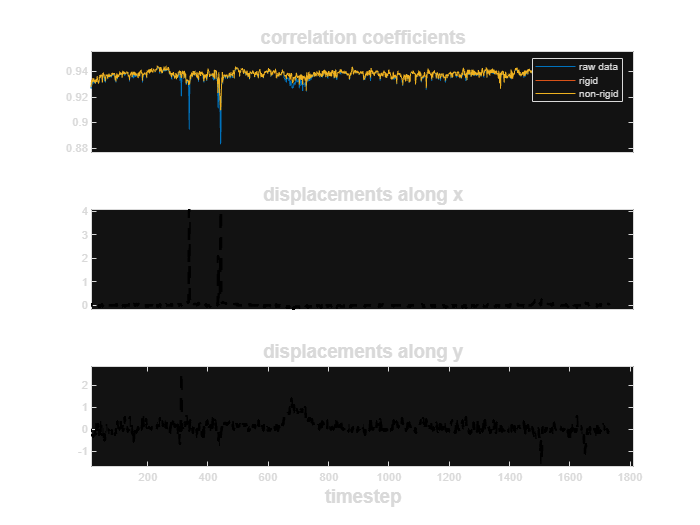

ground_truth_data = open(fullfile("C:\Users\RBO\Documents\data\ground_truth\high_res\_motion_correction_metrics_plane_30.fig"));

% Find all axes objects in the figures
gt_axesObjs = findobj(ground_truth_data, 'Type', 'axes');

gt_lineObjs = findobj(gt_axesObjs(i), 'Type', 'line');
v2_lineObjs = findobj(v2_axesObjs(i), 'Type', 'line');
 
% % Extract the X and Y data from the first line object in both datasets
X_gt = get(gt_lineObjs(1), 'XData');

Unrecognized function or variable 'gt_lineObjs'.

Y_gt = get(gt_lineObjs(1), 'YData');
X_v2 = get(gt_lineObjs(1), 'XData');
% 
% Y_v2 = get(v2_lineObjs(1), 'YData');
% Y_diff = Y_gt(:) - Y_v2(:);
% Y_diff = abs(Y_diff);
    
% Plot the difference for the current axis
f = figure;
plot(X_gt, Y_gt);
title('Difference in pixel shifts: ground truth vs V2');
xlabel('timestep');
ylabel = ('Number of Pixels in Y');
grid on;
fname = sprintf("High_res_diff_plane_%d.png", plane);
saveas(f, fullfile("C:\Users\RBO\Documents\data\high_res\corrected\figures\", fname));

%%
figure; subplot(1,2,1); set(gca,'xtick',[]); set(gca,'ytick',[]); imagesc(Y(:,:,200)); axis image; colormap 'gray';
subplot(1,2,2); imagesc(y(:,:,200)); axis image; colormap 'gray';
set(gca,'xtick',[]); set(gca,'ytick',[]);

clear('gcf');
imshowpair(Y(:,:,200),y(:,:,200),"diff")

## Extracted Images

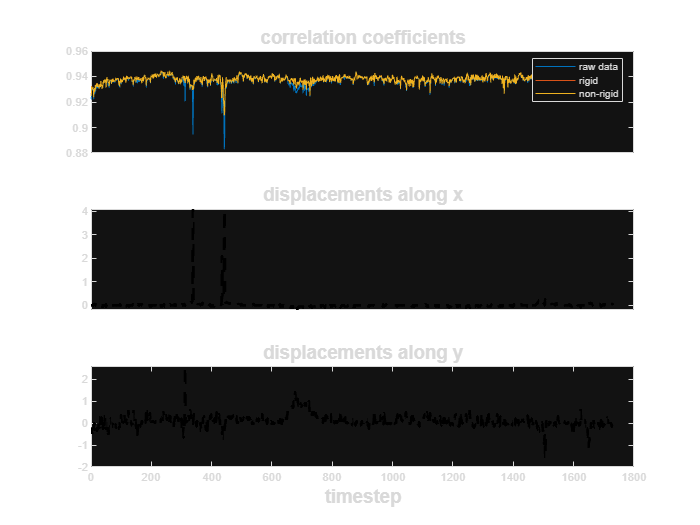

h5_fullfile = fullfile("C:\Users\RBO\Documents\data\high_res\corrected\motion_corrected_plane_1.h5");
mat_fullfile = fullfile("C:\Users\RBO\Documents\data\ground_truth\high_res\_motion_correction_metrics_plane_30.fig");
new_pipeline_shifts = h5read(h5_fullfile, '/shifts');
ground_truth_data = open(mat_fullfile);
saveas(ground_truth_data, fname, 'png');

h5info(h5_fullfile, '/').Datasets

ans = 3×1 struct array with fields:
    Name
    Datatype
    Dataspace
    ChunkSize
    FillValue
    Filters
    Attributes


## Comparison


% abs diff of images
gt_lineObjs = findobj(gt_axesObjs(i), 'Type', 'line');
    % Extract the X and Y data from the first line object in both datasets
X_gt = get(gt_lineObjs(1), 'XData');
Y_gt = get(gt_lineObjs(1), 'YData');
shifts_p = transpose(new_pipeline_shifts(:, 1));
shifts_p2 = transpose(new_pipeline_shifts(:, 2));
abs_diff1 = abs(shifts_p - Y_gt);
abs_diff2 = abs(shifts_p2 - Y_gt);
abs_diff3 = abs(Y_gt - shifts_p);
abs_diff4 = abs(Y_gt - shifts_p2);
max_diff1 = max(abs_diff1(:));
max_diff2 = max(abs_diff2(:));

max_diff3 = max(abs_diff3(:));
max_diff4 = max(abs_diff4(:));

mean_diff = mean(abs_diff(:));
disp(['Max difference: ', num2str(max_diff)]);
disp(['Mean difference: ', num2str(mean_diff)]);
num_frames = 2;
slice_idx = round(linspace(1, num_frames, min(num_frames, 10)));
figure;
for i = 1:length(slice_idx)
    idx = slice_idx(i);
    
    subplot(3, length(slice_idx), i);
    imagesc(new_pipeline_data(:,:,idx));
    title(['New Data Slice ', num2str(idx)]);
    axis equal; axis tight; colorbar;
    
    subplot(3, length(slice_idx), length(slice_idx) + i);
    imagesc(ground_truth_data(:,:,idx));
    title(['Ground Truth Slice ', num2str(idx)]);
    axis equal; axis tight; colorbar;
    
    subplot(3, length(slice_idx), 2*length(slice_idx) + i);
    imagesc(abs(new_pipeline_data(:,:,idx) - ground_truth_data(:,:,idx)));
    title(['Abs Difference Slice ', num2str(idx)]);
    axis equal; axis tight; colorbar;
end

% Loop through the second and third axes
for i = 2:3
    % Find the line objects in the current axis for both datasets
    gt_lineObjs = findobj(gt_axesObjs(i), 'Type', 'line');
    v2_lineObjs = findobj(v2_axesObjs(i), 'Type', 'line');

    % Extract the X and Y data from the first line object in both datasets
    X_gt = get(gt_lineObjs(1), 'XData');
    Y_gt = get(gt_lineObjs(1), 'YData');
    X_v2 = get(v2_lineObjs(1), 'XData');

    Y_v2 = get(v2_lineObjs(1), 'YData');
    Y_diff = Y_gt(:) - Y_v2(:);
    Y_diff = abs(Y_diff);
    
    % Plot the difference for the current axis
    f = figure;
    plot(X_gt, Y_diff);
    title('Difference in pixel shifts: ground truth vs V2');
    xlabel('timestep');
    ylabel = sprintf('Number of Pixels in %s', type_xy);
    grid on;
    fname = sprintf("%s_%d.png", dataset, i);
    saveas(f, fullfile("../../Documents/data/bi_hemisphere/registration/", fname));
end